clc; close all;

**Transferfunction of a Digital Resonator**

H(z) = $\frac{\left(z+1\right)\left(z-1\right)b_0 }{\left(z-{\textrm{ae}}^{\textrm{jw0}} \right)\left(z-{\textrm{ae}}^{-\textrm{jw0}} \right)}$ = $\frac{z^2 -2z-1}{z^2 -2\textrm{acos}\left(\textrm{w0}\right)z+a^2 }b_0 *\frac{z^{-2} }{z^{-2} }$

H(z) = $b_0 *\frac{1-2z^{-1} -z^{-2} }{1-2\textrm{acos}\left(\textrm{w0}\right)z^{-1} +a^2 z^{-2} }$

The coefficients can now be obtained from the transfer function equation.

%%Poles and Zeros
N = 1024;
fs = 8000;
a=0.9999;
b0 = 1;
f0 = 15;
w0 = 2*pi*f0/fs;

b = b0*[-1 -2 1];
a = [1 -2*a*cos(w0) a*a];

x = zeros(1,N);
x(1) = 1;

y = filter(b,a,x);

Plot the time domain signal in floatingpoint format

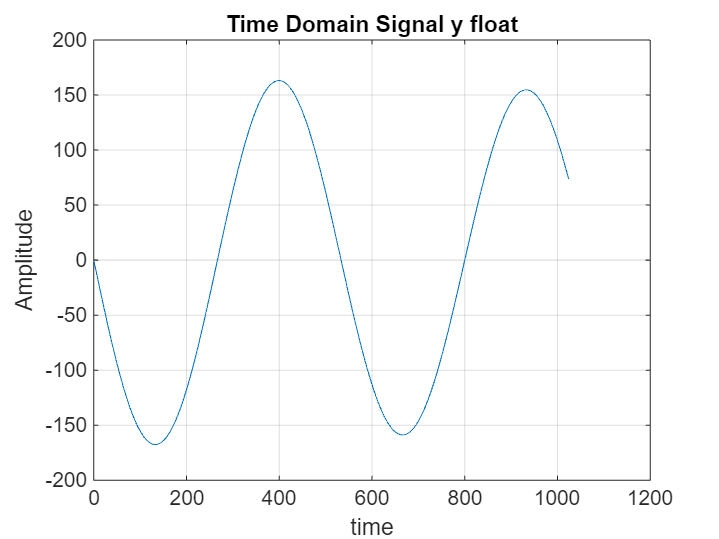

figure()
plot(y)
title('Time Domain Signal y float');
xlabel('time');
ylabel('Amplitude');
grid on;

Plot the FFT of the floatingpoint signal. By changing the f0 value, various frequencys can be applied.

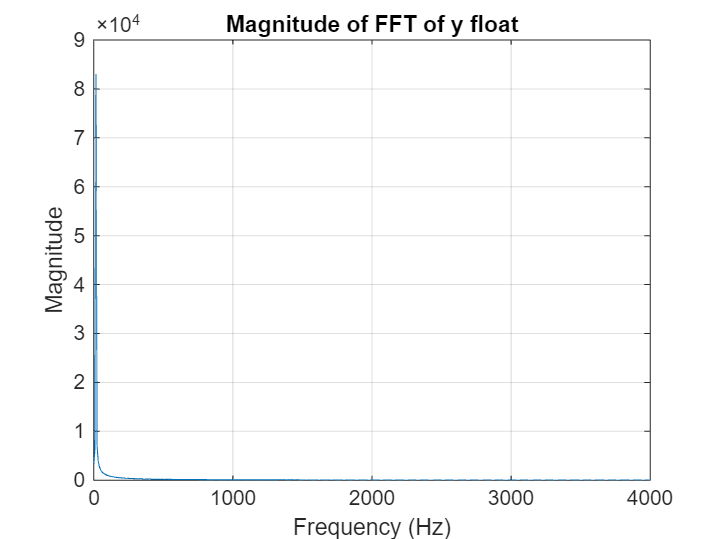

% Calculate the frequency axis
f = (0:length(fft(y))-1)*fs/length(fft(y));

% Plot the magnitude of the FFT
figure()
plot(f, abs(fft(y)));
title('Magnitude of FFT of y float');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 fs/2]);
grid on;

**Use of the convolution operation to implement an iir filter**

Another method could be to implement the convolution in Q15 format. Therefore, the coefficients need to be scaled down to this format. The `b` coefficients are divided by 2, and the `a` coefficients are divided by 4. **Important**: scale back the `a` coefficients in the feedback part. To remain in the Q15 format, the input signal also needs to be below a certain value. Here, 328 is chosen.

y_q15 = zeros(1,N);
b_q15 = round((2^(15)-1)*b/2);
a_q15 = round((2^(15)-1)*a/2);
x_q15 = zeros(1,N);
x_q15(1) = round((2^(15)-1)/100);
x_q15(1) = 100;
M = length(b_q15);
N = length(a_q15);
% Implement the IIR filter using for loops
for n = 1:length(x_q15) 
    % Initialize the current output sample to zero
    y_q15(n) = 0;
    % Apply the feedforward part
    for m = 1:M
        if n-m+1 > 0
            y_q15(n) = round(y_q15(n) + round((b_q15(m) * x_q15(n-m+1))/(2^(15))));
        end
    end
    % Apply the feedback part
    for k = 2:N
        if n-k+1 > 0
            y_q15(n) = round(y_q15(n) - round((2*a_q15(k) * y_q15(n-k+1))/(2^(15))));
        end
    end
end


The Plots show the time and frequency domain of the signal.

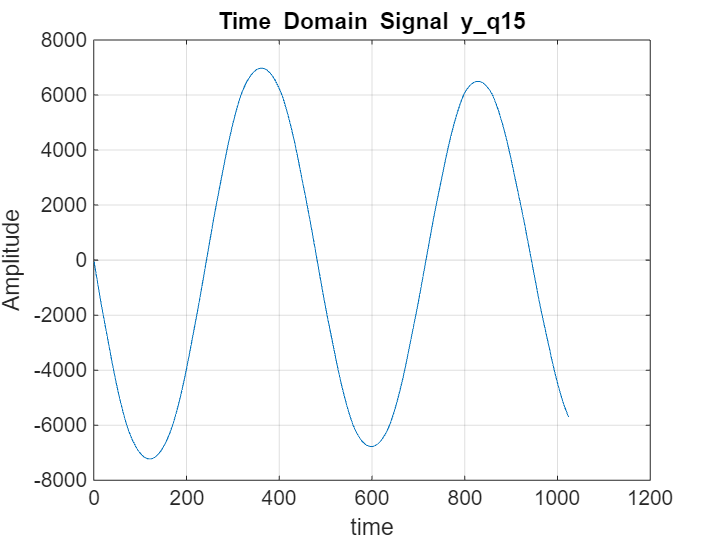

figure()
plot(y_q15)
title('Time Domain Signal y\_q15');
xlabel('time');
ylabel('Amplitude');
grid on;

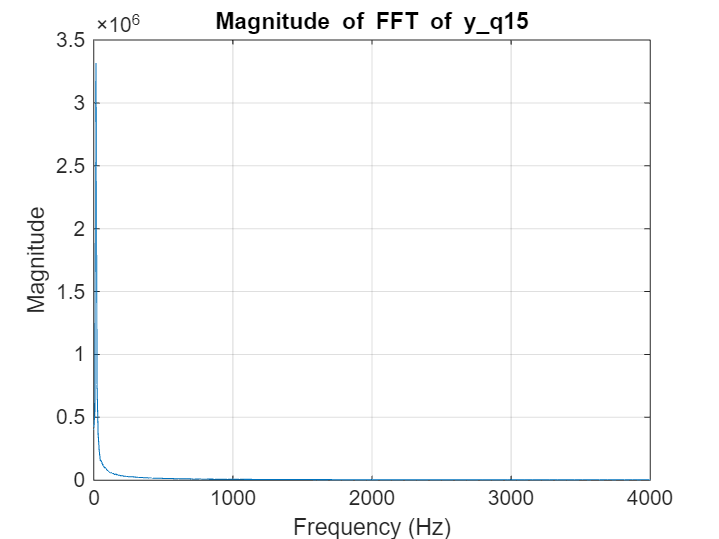

% Calculate the frequency axis
f = (0:length(fft(y_q15))-1)*fs/length(fft(y_q15));

% Plot the magnitude of the FFT
figure()
plot(f, abs(fft(y_q15)));
title('Magnitude of FFT of y\_q15');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 fs/2]);
grid on;

**Comparison**

To implement a Q15 filter, we must ensure that the Q15 range is maintained throughout all multiplications and summations. Therefore, it is necessary to scale both the input signal and the coefficients. Additionally, the multiplications in the convolution process must preserve the Q15 format. To Avoid an Underflow, the a coefficients need to be scaled back in the feedback loop.